clear
addpath('resources', 'scripts');

## Question 7.1

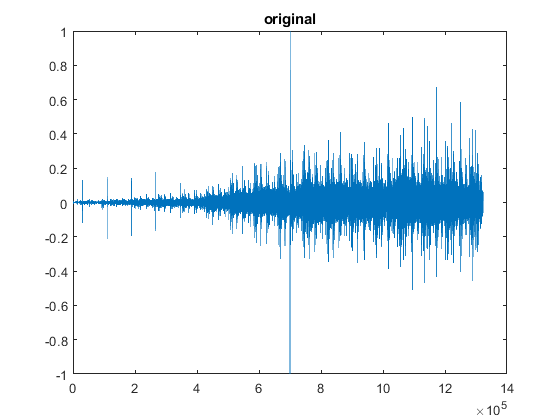

s = audioread('vinyl1.wav');

sound(s);

figure(1)
plot(s)
title('original')


s_manual = s;
for i = 1:length(cursor_info)
    range_start = (cursor_info(i).DataIndex)-0.1;
    range_end = (cursor_info(i).DataIndex)+0.1;
    s_manual(range_start : range_end) = 0;
end


%s_manual(6.99*10^5:7.01*10^5) = 0;

figure(2)
plot(s_manual)
title('manunal denoising')

## Question 7.2

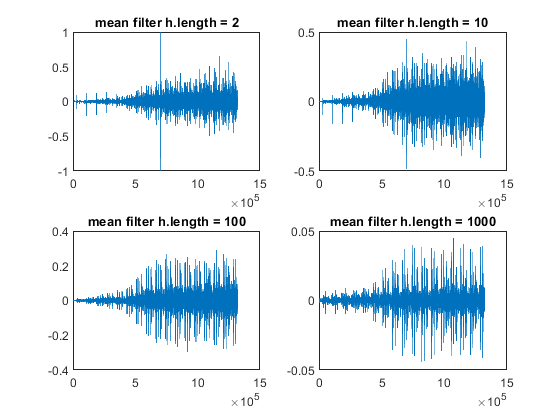

h1 = ones(1,2)/2;
h2 = ones(1,10)/10;
h3 = ones(1,100)/100;
h4 = ones(1,1000)/1000;

s_mean1 = filter(h1,1,s);
s_mean2 = filter(h2,1,s);
s_mean3 = filter(h3,1,s);
s_mean4 = filter(h4,1,s);

figure(3)
subplot(2,2,1)
plot(s_mean1)
title('mean filter h.length = 2')
subplot(2,2,2)
plot(s_mean2)
title('mean filter h.length = 10')
subplot(2,2,3)
plot(s_mean3)
title('mean filter h.length = 100')
subplot(2,2,4)
plot(s_mean4)
title('mean filter h.length = 1000')

## Question 7.3

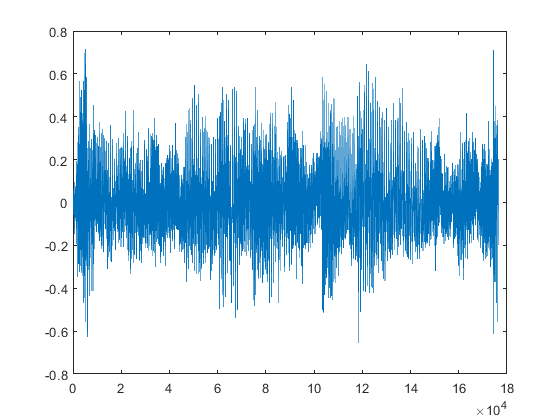

clear

cd1 = audioread('cd1.wav')';
h0 = [1/sqrt(2),1/sqrt(2)];
h1 = [-1/sqrt(2),1/sqrt(2)];

[a1,b1] = dwlt(cd1,h0,h1);
[a2,b2] = dwlt(a1,h0,h1);
[a3,b3] = dwlt(a2,h0,h1);

N = length(cd1);
med_b = median(b1);
sigma_est = mad(b1,1)/0.6745;
lambda = sigma_est*sqrt(2*log(N));

b1s = softThreshold(b1,lambda);
%cd1_thrshld = [a,softThreshold(b3,lambda), arrayfun(@(x) softThreshold(x,lambda),C)];
ca2 = idwlt(a3, softThreshold(b3,lambda),h0,h1);
ca1 = idwlt(ca2, softThreshold(b2,lambda),h0,h1);
cd1_idwlt3 = idwlt(ca1, softThreshold(b1,lambda),h0,h1);

plot(cd1_idwlt3)

lambda = sigma*sqrt(2*ln(N))

sigma_est = MAD(h(^1))/0.6745

MAD = median absolute deviation

h^(1) = highpass elements of first iteration

MAD: Definition A.4, Section A.1, Appendix A

page 495